% Incoming Missile Initial State for ATACMS
outputPath = fullfile(pwd,'Output Files/')
az0 = 0.15;
range0 = 50*1609.34; 
alt0 = 44000;
vx0 = -712;
vy0 = -100;
vz0 = -500;


% Simulation Constraints
horiz_calc = 90/4;
vert_calc = 44/4;
acc_calc = 5;
dt = .005;
max_iter = 22000;

% Run incoming missile profile
[impact_zone, impact_times, positions, velocities] = incomingMissileProfile(az0, range0, alt0, vx0, vy0, vz0, horiz_calc, vert_calc, acc_calc, dt, max_iter);

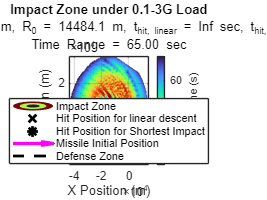

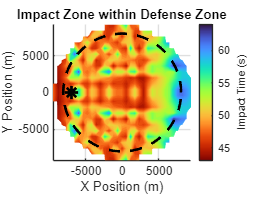

% Incoming Missile Initial State for ATACMS
outputPath = fullfile(pwd,'Output Files/');
az0 = 0;
range0 = 9*1609.34; 
alt0 = 9144;
vx0 = -343*3;
vy0 = 0;
vz0 = 0;

% Simulation Constraints
horiz_calc = 180/2;
vert_calc = 90/2;
acc_calc = 15;
dt = .1;
max_iter = 650;

% Run incoming missile profile
[impact_zone, impact_times, positions, velocities] = incomingMissileProfile(az0, range0, alt0, vx0, vy0, vz0, horiz_calc, vert_calc, acc_calc, dt, max_iter, outputPath);

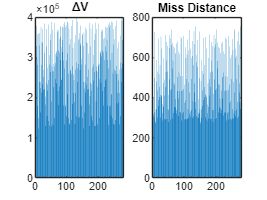

% Launcher initial state
launcher_pos = [0; 0; 0];       % [x; y; z] in meters
launcher_vel = [0; 0; 0];       % [vx; vy; vz] in m/s

% APN parameters
N = 4;                           % Navigation constant
K1 = 0.1;                        % Augmentation constant 1
K2 = 0.05;                       % Augmentation constant 2


% Run APN interception
[intercept_trajectories, total_delta_v, closest_distances] = apn_intercept(launcher_pos, launcher_vel, positions, velocities, N, K1, K2, dt);

% for i = length(closest_distances):-1:1
%     if closest_distances(i) > 14
%         closest_distances(i) = [];
%         total_delta_v(i) = [];
%     end
%     if total_delta_v(i) < 750
%         closest_distances(i) = [];
%         total_delta_v(i) = [];
%     end
% end

subplot(1,2,1)
bar((total_delta_v))
title("{\Delta}V")
subplot(1,2,2)
bar((closest_distances))
title("Miss Distance")
hold off

resultNum = 9%16330%11669

resultNum = 9

% Display results
fprintf("Miss Distance: %.1f m", closest_distances(resultNum))

Miss Distance: 496.9 m

fprintf("Delta V Required: %.1f m/s", total_delta_v(resultNum))

Delta V Required: 355636.3 m/s

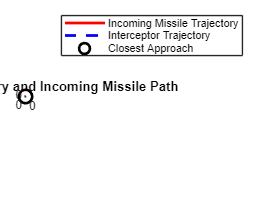

figure;
hold on;
grid on;
axis equal;
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Z Position (m)');
title('Interceptor Trajectory and Incoming Missile Path');
view(3)

incoming_missile = positions{resultNum};
plot3(incoming_missile(:,1), incoming_missile(:,2), incoming_missile(:,3), 'r-', 'LineWidth', 2);

% Plotting the interceptor trajectory up to closest approach
interceptor_traj = intercept_trajectories{resultNum};
plot3(interceptor_traj(:,1), interceptor_traj(:,2), interceptor_traj(:,3), 'b--', 'LineWidth', 2);

% Highlight the closest approach point
closest_point = interceptor_traj(end, :);
plot3(closest_point(1), closest_point(2), closest_point(3), 'ko', 'MarkerSize', 10, 'LineWidth', 2);

legend('Incoming Missile Trajectory', 'Interceptor Trajectory', 'Closest Approach');
hold off;